%Spectral Signal Subtraction Noise Reduction Method
filename='sample.wav';
outfile='SSSoutput.wav';
%function xfinal = Noise_Removal(filename,outfile)
%  Input: 
%       filename: the file name of the noisy speech
%       outfile:  the file name of the enhanced speech
%  Output:   
%       xfinal:   the time-signal of the enhanced speech

%if nargin<2
 %  return;
%end

## read from file

[x, Srate] = audioread(filename);  % x - Signal, Srate - Sampling rate, nBits- Bit resolution
x = x*32768;

## Initialize variables

len  = floor(20*Srate/1000); % Frame size in samples
if rem(len,2)==1, len=len+1; end  % Making the frame size even
PERC = 50; % window overlap in percent of frame size
len1 = floor(len*PERC/100);
len2 = len-len1; 

win     = hanning(len); % len point symmetric Hann window is created

%--- allocate memory and initialize various variables
nFFT       = len;
k          = 1;
img        = sqrt(-1);
x_old      = zeros(len1,1);
Nframes    = floor(length(x)/len1)-1;

fr         = Srate/nFFT;
fIndx      = 1:floor(4000/fr);
freqs      = 0:fr:(4000-fr);

aa         = 0.98;
gg         = 0.60;
c          = sqrt(pi)/2;
noise_mean = zeros(nFFT,1);
xfinal     = zeros(Nframes*len2,1);
ksi2       = [];

NIS        = 5; %initial silence
init       = 0;

## Noise magnitude calculations -

assuming that the first 5 frames is noise/silence

j = 1;
for k = 1:5
   noise_mean = noise_mean+abs(fft(win.*x(j:j+len-1),nFFT));
   j = j+len;
end
noise_mu = noise_mean/5;
noise_mu2 = noise_mu.^2;

## Processing

for n = 1:Nframes 
    insign = win.*x(k:k+len-1);
    %--- Take fourier transform of  frame
    spec  = fft(insign,nFFT);   
    sig   = abs(spec); % compute the magnitude
    sig2  = sig.^2;
    theta = angle(spec);    %save the phase information for each frame.
   
    if n>NIS
        if ~init
            %noise estimation initilization
          %  parameters = initialise_parameters(noise_mu2,Srate);
            init = 1;
        end
      %  parameters = noise_estimation(sig2,parameters);
       % noise_mu2 = parameters.noise_ps;
    end
   
    gamma = min(sig2./noise_mu2,20);  % post SNR
    if n==1
        gammak = gg + (1-gg)*gamma;
        ksi2 = aa+(1-aa)*max(gammak-1,0);
        ksi2 = max(ksi2,0.0025);
    else
        gammak = gg*gamma_prev + (1-gg)*gamma;
        post_SNR = (sqrt(gammak)-1).^2;
%       ksi2 = aa*Xk_prev./noise_mu2_old + (1-aa)*max(gammak-1,0);     % OLD a priori SNR   
        ksi2 = aa*Xk_prev./noise_mu2_old + (1-aa)*post_SNR;            % NEW a priori SNR   
        ksi2 = max(ksi2,0.0025);
    end

    noise_mu2_old = noise_mu2;
    
    % ---- define Cyd and Cxd ----------------
    Cyd = (gammak+1-ksi2)./(2*sqrt(gammak));
    Cxd = (gammak-1-ksi2)./(2*sqrt(ksi2));
    hw = sqrt((1-Cyd.^2)./(1-Cxd.^2));
    hw = min(hw,1);
       
    sig = sig.*hw;
    Xk_prev = sig.^2;
    gamma_prev = gammak;

    xi_w = ifft( hw .* spec); 
    xi_w = real( xi_w);
	
    % --- Overlap and add ---------------
    xfinal(k:k+len1-1) = x_old(1:len1) + xi_w(1:len1);
    x_old = xi_w(len1+1:len);
    k = k + len1;
end

xfinal = xfinal/32768;
if max(abs(xfinal))>32768
   xfinal = xfinal*24000/max(abs(xfinal));
   fprintf('Max amplitude exceeded 32768 for file %s\n',filename);   
end

audiowrite(outfile, xfinal, Srate);

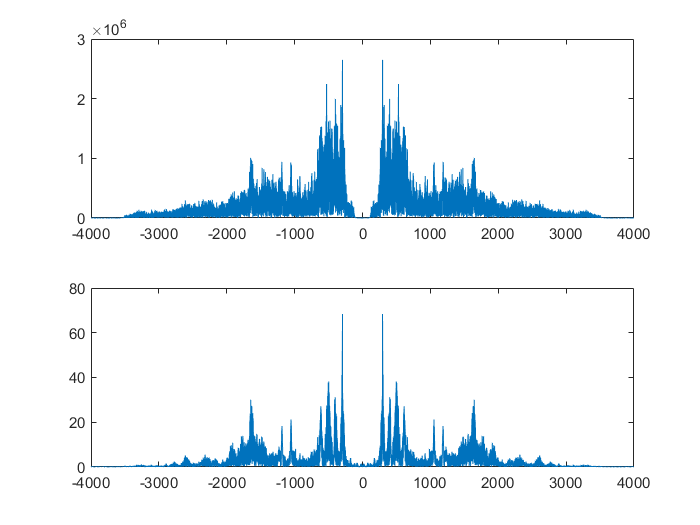

fVector1 = linspace(-Srate/2, Srate/2, length(x));
fVector2 = linspace(-Srate/2, Srate/2, length(xfinal));
figure(1);
xFFT = fftshift(fft(x));
xfinalFFT = fftshift(fft(xfinal));
subplot(2, 1, 1);
plot(fVector1, abs(xFFT));
subplot(2, 1, 2);
plot(fVector2, abs(xfinalFFT));